# Live script to test the two compartment model

% adding the model to the matlab path
addpath('D:\Projekte\two_comp_pump\model')


## generating stimulus


dt = 0.01; % [ms] time steps

% original stimulus used in Meiser 2019 in 0.01 ms bins
load('D:\Projekte\two_comp_pump\data\originalstimulus_binsize_0p01ms.mat')
Iinj = stim_Tcharacteristics .* 1000; % [pA]

## call model

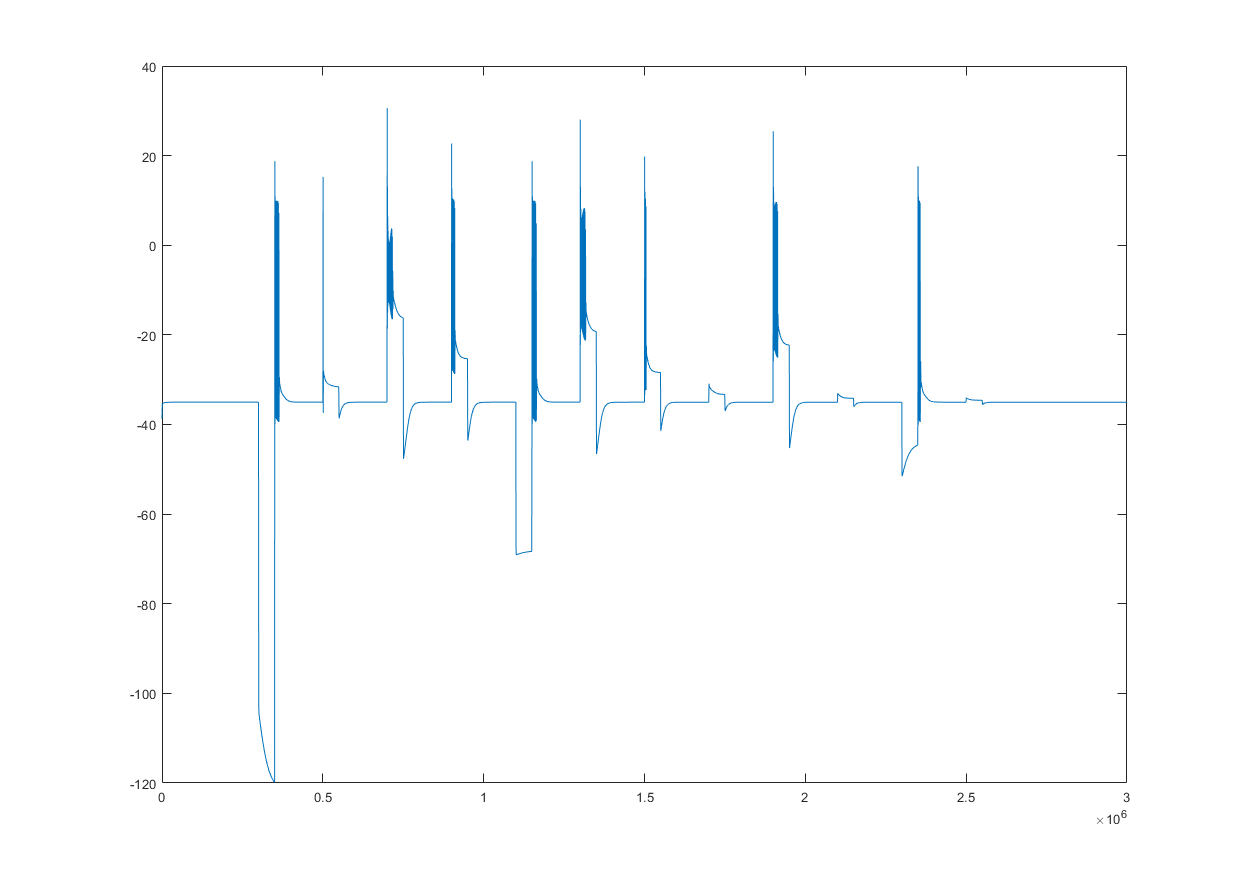

[V1, V2] = TcellDoublePump(Iinj, dt, 0);

plot(V1)